Quadrature weights and points for a triangle


$$~$$


### Syntax                                                                                                                                                                                                                                                                                                                                                                                                                                                                     

Q = quadtriangle(d)
Q = quadtriangle(d,Name,Value)

ans =    -0.7946   -0.8228
   -0.8669   -0.1811
   -0.9521    0.5753
   -0.0886   -0.8228
   -0.4095   -0.1811
   -0.7877    0.5753
    0.6174   -0.8228
    0.0480   -0.1811
   -0.6232    0.5753



$$~$$


### Description                                                                                                                                                                                                                                                                                                                                                                                                                                                                  

`Q = ``quadtriangle``(d)` returns the weights and points of a Gauss–Jacobi  product rule of degree `d` for numerically integrating over a (default) triangle defined by the vertices (-1,-1),(1,-1) and (-1,1). The output is stored as a structure `Q` with the following fields:

- `Q.Points =` the `n` quadrature points in an array of size `n×2`, where `Q.Points(:,1)` and `Q.Points(:,2)` are the `x` and `y` coordinates, respectively.

- `Q.Weights` = the corresponding quadrature weights stored in a column vector of length `n`.

- `Q.Properties` = contains (sub)fields describing the `.Degree` (the input value `d`), the `.Type` (see description below) and the` .Domain` of integration of the quadrature rule.

`Q = ``quadtriangle``(d,Name,Value)` same as above but with additional control over the type of rules returned. Options include specification of the following `Name-Value` pair arguments: 

`'Domain'` — Triangular domain

`[ -1 -1; 1 -1; -1 1 ]` (default) │` [ x1 y2; x2 y2; x3 y3 ]` │ `[ ]` 

The triangular domain over which the weights and points are defined, specified as a `3×2` array of the (x,y) vertices of the triangle, i.e.,  `T = [x1 y2; x2 y2; x3 y3]`, or as an empty array. 

In the case of the latter option, the returned quadrature points consist of the first two barycentric (or area) coordinates, and the returned quadrature weights are scaled such that they sum to 1. (Note: The third barycentric coordinate for the points can easily be computed as `1-Q.Points(:,1)-Q.Points(:,2)`.)

`'Type'` — Type of quadrature rule

`'product'` (default) │ `'nonproduct'`

The type of quadrature rule may be specified as `'product'` (default), in which case the points and weights of a Gauss–Jacobi product rule are returned, or as `'nonproduct'`. Product rules can be of arbitrary degree, while nonproduct rules are currently only available up to degree 25.

The following additional `Name-Value` pairs are available for nonproduct rules:

`'Symmetry'` — Symmetry of the quadrature rule

`'full' `(default) │` 'allowAsymmetric'`

The `'full' `(default) value requires the quadrature rule to be fully symmetric. The value 'allowAsymmetric' allows asymmetric quadrature rules of lower point count than the full symmetry rules to be returned when available. (Note: Some quadrature rules possess so-called partial symmetry, though no distinction is made here between asymmetric and partially symmetric rules, i.e., a rule is classified as either fully symmetric or asymmetric.)

`'Weights'` — Quadrature weight conditions

`'positive'` (default) │ `'allowNegative'`

The `'postive' `(default) value requires all quadrature weights to be positive. The value `'allowNegative'` allows quadrature rules with negative weight(s) of lower point count than the positive weight rules to be returned when available.

`'Points' `— Location of quadrature points

`'inside' `(default) |` 'allowOutside'`

The `'inside'` (default) requires all points to be inside the triangle. The value `'allowOutside'` allows quadrature rules with point(s) outside the triangle of lower point count than the quadrature rules with all points inside to be returned when available.

Note: The default `Name-Value` pairs for nonproduct rules are set such that the minimal-point, fully symmetric so-called **PI** rule (that is, all weights are **P**ositive and all points are **I**nside the triangle) of degree `d` is returned. Fully symmetric PI rules are generally preferred among practitioners.

### Examples                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        

**Example 1 **$-$**  The derivation of product rules for the triangle**

One method of applying quadrature over a triangle involves a (nonlinear) transformation of the triangular domain to a square as shown below.

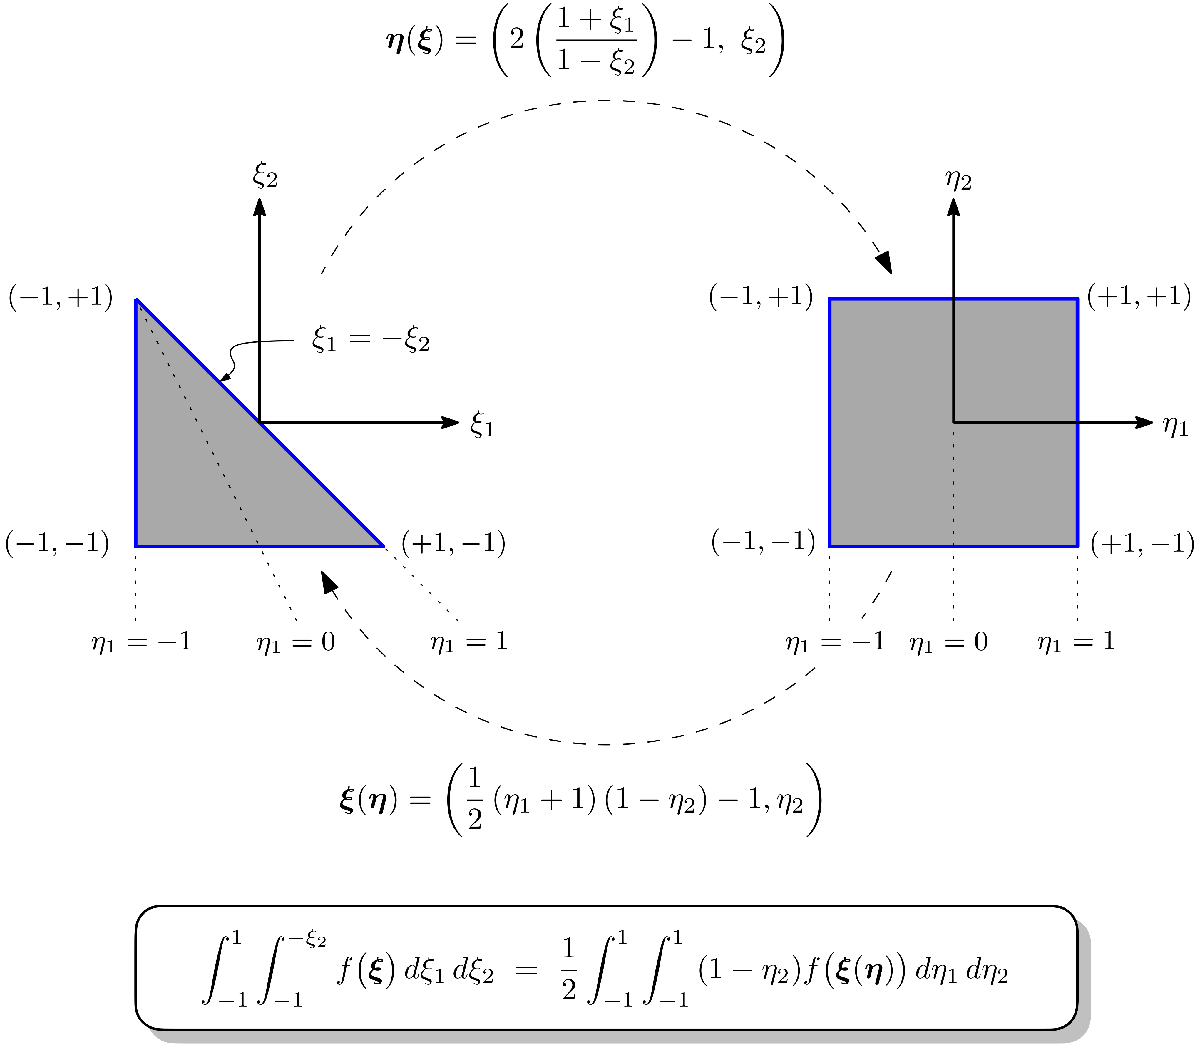

This allows one to construct a so-called ***product*** rule (the default type of rule for the `quadtriangle` function) formed from Gauss–Jacobi quadrature rules applied in each $\eta$ direction. Note that this transformation introduces a "weight function" of $(1-\eta_2)$ as shown in the integral above. This requires the use of a Gauss–Jacobi quadrature rule of weight $(\alpha,\beta)=(1,0)$ in the $\eta_2$ direction, which can be paired with a Gauss–Jacobi  quadrature rule of weight $(\alpha,\beta)=(0,0)$ (equivalently, standard Gauss–Legendre quadrature) in the $\eta_1$ direction. 

This example demonstrates how the triangle products rules are computed within the `quadtriangle `function using the (one-dimensional) [quadGaussJacobi](http://u.osu.edu/kubatko.3/codes_and_software/quadtools/quadgaussjacobi/) function and the transformations illustrated in the figure above. Consider a product rule of degree 4 obtained using the `quadtriangle` function, which has the following 9 points:

Qtriangle = quadtriangle(4);
Qtriangle.Points

This point set was constructed in three steps: 1) By obtaining two 3-point (degree 4) Gauss-Jacobi quadrature rules — one of weight $(\alpha,\beta)=(0,0)$ in the $\eta_1$ direction and one of weight $(\alpha,\beta)=(1,0)$ in the $\eta_2$ direction, i.e.,

Q1 = quadGaussJacobi(3,0,0);
Q2 = quadGaussJacobi(3,1,0);

2) Taking their [Cartesian product](https://en.wikipedia.org/wiki/Cartesian_product) using the `meshgrid` function

[eta1,eta2] = meshgrid(Q1.Points,Q2.Points);

ans =    -0.7946   -0.8228
   -0.8669   -0.1811
   -0.9521    0.5753
   -0.0886   -0.8228
   -0.4095   -0.1811
   -0.7877    0.5753
    0.6174   -0.8228
    0.0480   -0.1811
   -0.6232    0.5753


and then 3) Applying the transformation from the square ($\eta$ cooridates) to the triangle ($\xi$coordinates) , i.e.,

[ 1/2*(1+eta1(:)).*(1-eta2(:))-1,eta2(:) ]

ans =     0.2233
    0.2547
    0.0776
    0.3572
    0.4075
    0.1241
    0.2233
    0.2547
    0.0776


which is equilvalent to the point set above.

The weights for the product rule are obtained by taking the [Kronecker product](https://en.wikipedia.org/wiki/Kronecker_product) of the two weight sets (scaled by 1/2), i.e.,

1/2*kron(Q1.Weights,Q2.Weights)

ans =     0.2233
    0.2547
    0.0776
    0.3572
    0.4075
    0.1241
    0.2233
    0.2547
    0.0776


 which is equivalent to 

Qtriangle.Weights

**Example 2 **$-$**  The advantages and disadvantages of using product quadrature rules**

The main advantage of using product rules for the triangle is the abiliy to easily construct quadrature rules of arbitrary degree. Two disadvantages are the use of a greater number of points than necessary for a given degree and the "clustering" of points near the top vertex, which is "collapsed" when transforming from the square back to the triangle. Nonproduct rules, which are specifically designed for directly integrating over the triangle, do not possess these two disadvantages.

(Note: The main disadvantage of nonproduct rules is that there is no simple, direct method of constructing them for arbitary degrees, though rules up to quite a high degree can be found in the literature and rules up to degree 25 are included in the `quadtriangle` function).

Consider, for example, the bipolymonial $P(x,y) = 2x^8 + x^3y^4$ defined as an anonymous function:

P = @(x,y) 2*x.^8 + x.^3.*y.^4;

Qp = struct with fields:
        Points: [25×2 double]
       Weights: [25×1 double]
    Properties: [1×1 struct]


integrated over the default triangle, which has an exact value of $2/5$. This can be computed using a product rule of degree 8

Qp = quadtriangle(8,'Type','product')

Qnp = struct with fields:
        Points: [16×2 double]
       Weights: [16×1 double]
    Properties: [1×1 struct]


which has 25 points, or a nonproduct rule

Qnp = quadtriangle(8,'Type','nonproduct')

Ip = 0.4000

which has only 16 points. In either case, applying the quadrature rule, it is found:

Ip  = dot(Qp.Weights, P(Qp.Points(:,1), Qp.Points(:,2)))  % Product rule

Inp = 0.4000

Inp = dot(Qnp.Weights,P(Qnp.Points(:,1),Qnp.Points(:,2))) % Nonproduct rule

which are both exact. 

Using the [quadplot](http://u.osu.edu/kubatko.3/codes_and_software/quadtools/quadplot/) function, it can be observed that a number of the product quadrature points are clustered near the top vertex:

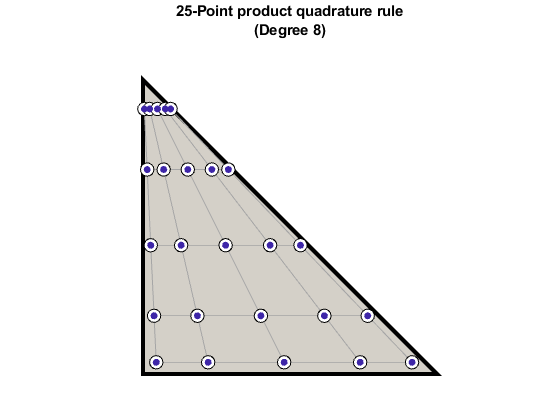

figure
quadplot(Qp)

while the nonproduct quadrature points are more evenly distributed over the triangle:

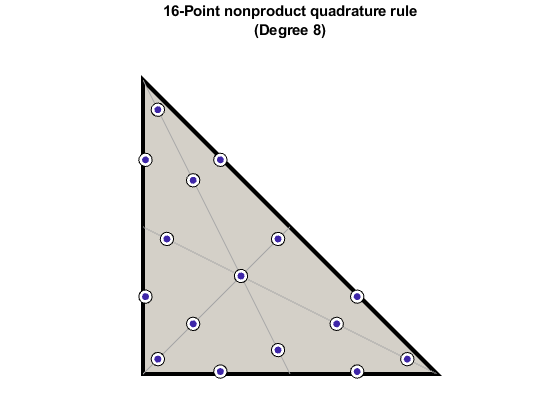

figure
quadplot(Qnp)

The latter is generally viewed as being more favorable.

#### *This function is part of........*